# `计算物理第二章作业`

## `1、教材习题`

### `    2-1 Show that the error associated with the trapezoidal rule of integration for the definite integral`

### 
$$I_{\left[ a,b \right]}=\int_a^b f(x) \mathrm d x$$


### `is `$-(b-a)h^2f^{\prime \prime}(\xi)/12$`, where `$f^{\prime \prime}(\xi)$` is the average value of the second-order derivative of `$f(x)$`in the interval `$x=\left[a,b\right]$`.`

`Solution: According to Euler-Maclaurin summation formula for integrals:`

####    
$$\int_a^b f(x) \mathrm dx=h(\frac{1}{2}f_0+f_1+\dots+f_{N-1}+\frac{1}{2}f_N)-\frac{B_2}{2!}h^2(f^\prime_N-f^\prime_0)-\dots-\frac{B_{2k}}{(2k)!}h^{2k}(f^{(2k-1)}_N-f^{(2k-1)}_0)-\dots$$


`So the total error of trapezoidal rule of integration for this integral is(`$B_2=\frac{1}{6}$`) `

#### 
$$\Delta I_{[a,b]}=\int_a^bf(x)\mathrm dx-I_{[a,b]}\approx-\frac{B_2}{2!}h^2(f^\prime_N-f^\prime_0)=-\frac{(b-a)h^2}{12}\frac{f^\prime_N-f^\prime_0}{b-a}=-\frac{(b-a)h^2}{12}f^{\prime \prime}(\xi)$$


### `    2-2 Compare the efficiencies of calculating the normal probability function integral`

### 
$$A(x)=\frac{1}{\sqrt{2}} \int_{-x}^{+x} e^{-t^2}\mathrm dt$$


### `using the trapezoidal rule, Simpson's rule, and a Mento Carlo method.`

`Solution:`

`利用计算时间作为效率的比较`

clear
format long
a = -10;
b = 10;
n = 2000;
h = (b-a)/n;
x = a:h:b;

#### `trapezoidal rule:`

tic
y1 = 1/sqrt(2)*exp(-x.^2);
y1(2:1:n) = 2*y1(2:1:n);
s1 = h*sum(y1)/2;
t1 = toc;

#### `Simpson's rule:`

tic
y2 = 1/sqrt(2)*exp(-x.^2);
y2(2:2:n) = 4*y2(2:2:n);
y2(3:2:n-1) = 2*y2(3:2:n-1);
s2 = h/3*sum(y2);
t2 = toc;

#### `Mento Carlo method:`

tic
t = rand(1,n);
x = a+(b-a)*t;
y3 = 1/sqrt(2)*exp(-x.^2);
s3 = sum(y3)*(b-a)/n;
t3 = toc;

精确值

fun = @(x,y) 1/sqrt(2)*exp(-x.^2);
 I = integral(fun,-10,10);

`输出：`

disp(['精确值为：',num2str(I,10)])

精确值为：1.253314137


 disp(['梯形法结果为：',num2str(s1,10),'   所用时间为：',num2str(t1,10),'   与精确值的绝对误差为：',num2str(abs(s1-I),10)])

梯形法结果为：1.253314137   所用时间为：0.0045449   与精确值的绝对误差为：4.396483178e-14


 disp(['辛普森法结果为：',num2str(s2,10),'   所用时间为：',num2str(t2,10),'   与精确值的绝对误差为：',num2str(abs(s2-I),10)])

辛普森法结果为：1.253314137   所用时间为：0.0068689   与精确值的绝对误差为：4.06341627e-14


 disp(['蒙特卡洛法结果为：',num2str(s3,10),'   所用时间为：',num2str(t3,10),'   与精确值的绝对误差为：',num2str(abs(s3-I),10)])

蒙特卡洛法结果为：1.299787038   所用时间为：0.0073597   与精确值的绝对误差为：0.04647290102


通过比较可以发现，在节点数相同的情况下，用时最短的是梯形法，精度最高的是辛普森方法。

### `    2-3 Use a Gauss-Legendre quadrature of order `$n=4$` to evaluate the integral`

### 
$$I(a)=\int_{-a}^{+a}x^9\ \mathrm dx$$


### `for an arbitrarily value of `$a$`. The exact value for this integral is zero. Use the same method to calculate the integral `

### 
$$I(b)=\int_{-a}^{+a}x^8\mathrm dx$$


### `The exact value is `$2a^9/9$`. Compare the accuracies obtained for the two integrals and explain why there is a large difference.`

`Solution:`

clear
format long
%定义积分区间
a = -1;%区间下限
b = 1;%区间上限
node = [-0.8611363,-0.3399810,0.3399810,0.8611363];%4阶高斯积分的节点
x = (b-a)/2*node+(a+b)/2;
%计算第一个积分
y1 = x.^9;
y1(1:3:4) = 0.3478549*y1(1:3:4);
y1(2:3) = 0.6521451*y1(2:3);
s1 = (b-a)/2*sum(y1);
%计算第二个积分
y2 = x.^8;
y2(1:3:4) = 0.3478549*y2(1:3:4);
y2(2:3) = 0.6521451*y2(2:3);
s2 = (b-a)/2*sum(y2);

%输出
disp(['第一个结果为：',num2str(s1),'与精确值的绝对误差为：',num2str(abs(s1-0))])

第一个结果为：0与精确值的绝对误差为：0


disp(['第二个结果为：',num2str(s2),'与精确值的绝对误差为：',num2str(abs(a^2*2/9-s2))])

第二个结果为：0.21061与精确值的绝对误差为：0.01161


第二个积分产生的误差的原因是：

对于4阶的高斯积分方法，最高可以展开到$x^7$,误差产生在$x^8$及其以后的高阶项，所以计算$x^8$时会产生误差。

### `2-6 Use a Taylor series expansion to derive the central difference result given in Eq.(2-55) for the second-order derivative of `$f(x)$ `at `$x=x_k$,

### 
$$f^{\prime \prime}(x_k)=\frac{f_{k+1}-2f_k+f_{k-1}}{h^2}$$


### `Calculate the leading order correction term in powers of `$h$`.`

`Solution:`

`将`$f(x)$在点$x_k$处泰勒展开，可以得到：

#### 
$$f(x)=f\left(x_{k}\right)+f^{\prime}\left(x_{k}\right)\left(x-x_{k}\right)+\frac{f^{\prime \prime}\left(x_{k}\right)}{2 !}\left(x-x_{k}\right)^{2}+\ldots$$


将$x_{k+1}$代入$f(x)$,可以得到：

#### 
$$f\left(x_{k+1}\right)= f\left(x_{k}\right)+f^{\prime}\left(x_{k}\right)\left(x_{k+1}-x_{k}\right)+\frac{f^{\prime \prime}\left(x_{k}\right)}{2 !}\left(x_{k+1}-x_{k}\right)^{2}+\ldots$$


因为$h=x_{k+1}-x_k$, $f^{\prime}(x)=\frac{f(x_{k+1})-f(x_{k-1})}{2h}$,所以：

#### 
$$f^{\prime \prime}(x_k)=\frac{f_{k+1}-2f_k+f_{k-1}}{h^2}$$


### `2-7 Use the same method as for Problem 2-6 to derive the five-point approximate result`

### 
$$f^{\prime \prime}(x_k)=\frac{1}{12h^2}(-f_{k-2}+16f_{k-1}-30f_k+16f_{k+1}-f_{k+2})+\frac{h^4}{90}f^{(6)}(x)+...$$


### `given earlier in Eq.(2-61)`

`Solution: 利用taylor展开可以得到：`

#### 
$$$f\left(x_{k+1}\right)=f\left(x_{k}\right)+f^{\prime}\left(x_{k}\right) h+\frac{1}{2 !} f^{\prime \prime}\left(x_{k}\right) h^{2}+\frac{1}{3 !} f^{\prime \prime \prime}\left(x_{k}\right) h^{3}+\frac{1}{4 !} f^{(4)}\left(\xi_{1}\right) h^{4}\\f\left(x_{k-1}\right)=f\left(x_{k}\right)-f^{\prime}\left(x_{k}\right) h+\frac{1}{2 !} f^{\prime \prime}\left(x_{k}\right) h^{2}-\frac{1}{3 !} f^{\prime \prime \prime}\left(x_{k}\right) h^{3}+\frac{1}{4 !} f^{(4)}\left(\xi_{2}\right) h^{4}\\f\left(x_{k+2}\right)=f\left(x_{k}\right)+f^{\prime}\left(x_{k}\right) 2 h+\frac{1}{2 !} f^{\prime \prime}\left(x_{k}\right)(2 h)^{2}+\frac{1}{3 !} f^{\prime \prime \prime}\left(x_{k}\right)(2 h)^{3}+\frac{1}{4 !} f^{(4)}\left(\xi_{3}\right)(2 h)^{4}\\f\left(x_{k-2}\right)=f\left(x_{k}\right)-f^{\prime}\left(x_{k}\right) 2 h+\frac{1}{2 !} f^{\prime \prime}\left(x_{k}\right)(2 h)^{2}-\frac{1}{3 !} f^{\prime \prime \prime}\left(x_{k}\right)(2 h)^{3}+\frac{1}{4 !} f^{(4)}\left(\xi_{4}\right)(2 h)^{4}$$


再利用中值定理，从而可以得到五点公式为：

#### 
$$f^{\prime \prime}(x_k)=\frac{1}{12h^2}(-f_{k-2}+16f_{k-1}-30f_k+16f_{k+1}-f_{k+2})+O(h^4)$$


### `2-9 Use a Monte Carlo Method to carry out integral `

### 
$$I=\int_{0}^{1}\frac{\mathrm dx}{1+x^2}$$


### `The result may be tested with the help of the relation `$\int_0^1\frac{\mathrm dx}{1+x^2}=tan^{-1}x\left|^1_0=\frac{\pi}{4}$

### `Is this a good way to obtain the value of `$\pi$` or just a way to test the random number generator used in the calculation?`

`Solution:`

clear
format long
a = 0;
b = 1;
n = 5000;
t = rand(1,n);
x = a+(b-a)*t;
y = 1./(1+x.^2);
s = sum(y)*(b-a)/n

s =    0.783963290619122


#### `It's a good way to obtain the value of `$\pi$`.`

## `2、误差函数`$erf(x)$`的定义为`$erf(x)=\frac{2}{\sqrt{\pi}}\int_0^xe^{-x^2}\ \mathrm dx$`，试计算`$x=0.1,0.2,0.3,\dots,1.0$`时的函数值。`

### `提示与要求：`

### `（1）具体算法任意选择，误差阈值要求1e-10；`

### `（2）计算结果与matlab内建误差函数erf(``x``)对比，给出绝对误差。`

`利用辛普森法计算`

clear
format long
a = 0;
b = 0.1;
epsilon_0 = 1e-10;%设置误差阈值
for i = 1:10
    n = 2;
    s = 0;
    s_n = 1;
    while (abs(s_n-s) > epsilon_0)
        h = (b-a)/n;
        x = a:h:b;
        y = 2/sqrt(pi)*exp(-x.^2);
        y(2:2:n) = 4*y(2:2:n);
        y(3:2:n-1) = 2*y(3:2:n-1);
        s = s_n;
        s_n = h*sum(y)/3;
        n = n+2;
    end
    N(i) = n;
    B(i) = b;
    S(i) = s_n;
    err(i) = abs(s_n-erf(b));
    b = b+0.1;
end
B
N
S
err

积分上限为：

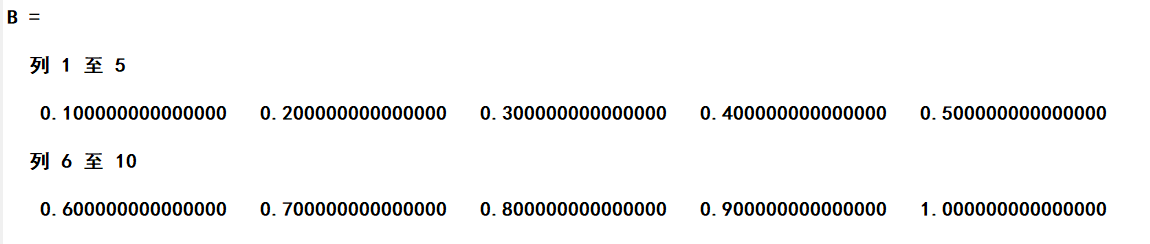

迭代后的区间划分数：

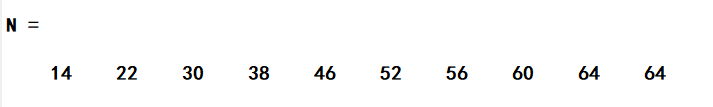

积分结果：

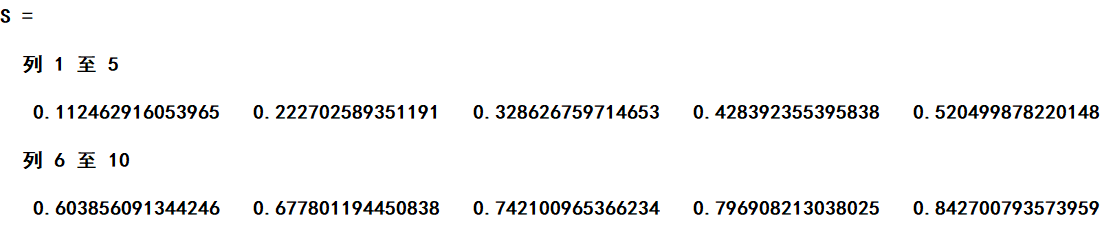

与精确值的绝对误差

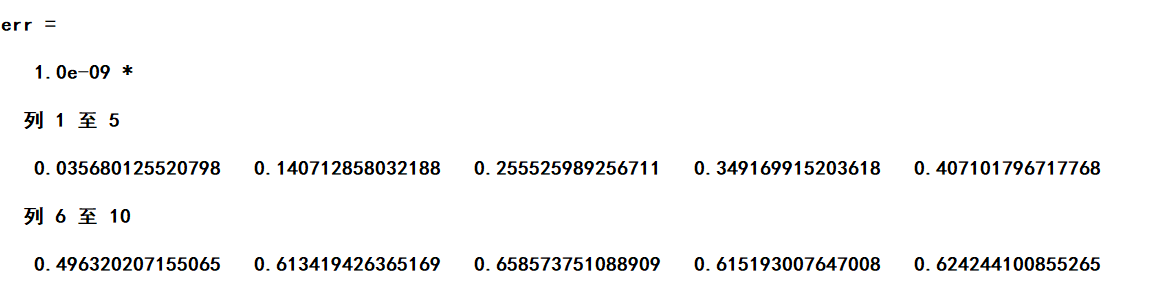

## `3、利用梯形公式、辛普森公式和蒙特卡洛方法计算二重积分`$I=\int_{D_{xy}}\frac{\sin (x+y)}{x+y}\mathrm d\sigma$`的数值结果，将数值计算结果与精确值对比,并对比三种算法的精度及效率，积分区域`$D_{xy}$`为矩形`$0 \le x \le 4,-1\le y \le 2$`。`

%第三题：计算二重积分
%初始化
clear
format long
%定义积分区间
a_x = 0;
b_x = 4;
a_y = -1;
b_y = 2;
%定义积分区间数
N_x = 10000;
N_y = 10000;
%步长
h_x = (b_x-a_x)/N_x;
h_y = (b_y-a_y)/N_y;
%划分区间
[x,y] = meshgrid(a_x:h_x:b_x,a_y:h_y:b_y);

#### `1 trapezoidal rule:`

tic
z1 = (sin(x+y)./(x+y))';
z1(2:N_x,1) = 2*z1(2:N_x,1);
z1(2:N_x,N_y+1) = 2*z1(2:N_x,N_y+1);
z1(1,2:N_y) = 2*z1(1,2:N_y);
z1(N_x+1,2:N_y) = 2*z1(N_x+1,2:N_y);
z1(2:N_x,2:N_y) = 4*z1(2:N_x,2:N_y);
i = isnan(z1);
z1(i) = 0;
s1 = h_x*h_y*sum(z1,'all')/4;
t1 = toc;

`2 Simpson's rule:`

tic
z2 = (sin(x+y)./(x+y))';
z2(3:2:N_x-1,1) = 2*z2(3:2:N_x-1,1);
z2(N_x+1,3:2:N_y-1) = 2*z2(N_x+1,3:2:N_y-1);
z2(1,3:2:N_y-1) = 2*z2(1,3:2:N_y-1);
z2(3:2:N_x-1,N_y+1) = 2*z2(3:2:N_x-1,N_y+1);
z2(N_x+1,4:2:N_y) = 4*z2(N_x+1,4:2:N_y);
z2(1,4:2:N_y) = 4*z2(1,4:2:N_y);
z2(4:2:N_x,1) = 4*z2(4:2:N_x,1);
z2(4:2:N_x,N_y+1) = 4*z2(4:2:N_x,N_y+1);
z2(3:2:N_x-1,3:2:N_y-1) = 4*z2(3:2:N_x-1,3:2:N_y-1);
z2(2:2:N_x,3:2:N_y-1) = 8*z2(2:2:N_x,3:2:N_y-1);
z2(3:2:N_x-1,2:2:N_y) = 8*z2(3:2:N_x-1,2:2:N_y);
z2(2:2:N_x,2:2:N_y) = 16*z2(2:2:N_x,2:2:N_y);
i = isnan(z2);
z2(i) = 0;
s2 = h_x*h_y*sum(z2,'all')/9;
t2 = toc;

`3 Monte Carlo method:`

tic
t_x = rand(1,N_x);
t_y = rand(1,N_y);
x = a_x+(b_x-a_x)*t_x;
y = a_y+(b_y-a_y)*t_y;
[x,y] = meshgrid(x,y);
z3 = sin(x+y)./(x+y);
i = isnan(z3);
z3(i) = 0;
s3 = sum(z3,'all')*(b_x-a_x)*(b_y-a_y)/(N_x*N_y);
t3 = toc;

精确值

fun = @(x,y) sin(x+y)./(x+y);
 I = integral2(fun,0,4,-1,2);

结果输出

 disp(['精确值为：',num2str(I,10)])

精确值为：3.644036766


 disp(['梯形法结果为：',num2str(s1,10),'   所用时间为：',num2str(t1,10),'   与精确值的绝对误差为：',num2str(abs(s1-I),10)])

梯形法结果为：3.643988712   所用时间为：2.5266252   与精确值的绝对误差为：4.805393638e-05


 disp(['辛普森法结果为：',num2str(s2,10),'   所用时间为：',num2str(t2,10),'   与精确值的绝对误差为：',num2str(abs(s2-I),10)])

辛普森法结果为：3.644004545   所用时间为：2.4756295   与精确值的绝对误差为：3.222076298e-05


 disp(['蒙特卡洛法结果为：',num2str(s3,10),'   所用时间为：',num2str(t3,10),'   与精确值的绝对误差为：',num2str(abs(s3-I),10)]) 

蒙特卡洛法结果为：3.620609763   所用时间为：1.8408441   与精确值的绝对误差为：0.02342700272


从结果可以看出计算所用时间最短的是蒙特卡洛方法，计算精度最高的是辛普森法。

## `4、已知室温下氢分子的最概然速率`$v_p=1578\ \text{m/s}$`，麦克斯韦-玻尔兹曼速率分布函数为`$f(v)=4\pi v^2 \Big(\frac{m}{2\pi kT}\Big)^{\frac{3}{2}}\exp\Big(-\frac{mv^2}{2kT}\Big)$

## `试求室温下氢分子平均速率`$v_{\text{ave}}=\int_{0}^\infty vf(v)\mathrm dv$`和均方根速率`$v_{\text{rms}}=\left[\int_{0}^\infty v^2f(v)\mathrm dv\right]^\frac{1}{2}$`。`

### `提示与要求：`

### `（1）麦克斯韦-玻尔兹曼速率分布函数以最概然速率`$v_p=\sqrt{\frac{2kT}{m}}$`可表示为`$f(v)=\frac{4}{\sqrt{\pi}}\left(\frac{v^2}{v_p^3}\right)\exp\left( -\frac{v^2}{v_p^3}\right)$`；`

### `（2）计算结果与理论关系`$v_p:v_{\text{ave}}:v_{\text{rms}}=1:\frac{2}{\sqrt{\pi}}:\sqrt{\frac{3}{2}}$`对比。`

%第四题

%初始化
clear
format long
%定义最概然速率
v_p = 1578;
%定义积分区间
a = 0;
b = 10*v_p;%由于函数收敛快速，所以b取8倍以上的v_p
%定义区间数
n = 20000;
%步长
h = (b-a)/n;
x = a:h:b;
y = (4/sqrt(pi)*(x.^2/v_p^3).*exp(-x.^2/v_p^2));
%计算平均速率
y1 = x.*y;
y1(2:2:n) = 4*y1(2:2:n);
y1(3:2:n-1) = 2*y1(3:2:n-1);
s1 = h/3*sum(y1);
%计算方均根速率
y2 = x.^2.*y;
y2(2:2:n) = 4*y2(2:2:n);
y2(3:2:n-1) = 2*y2(3:2:n-1);
s2 = sqrt(h/3*sum(y2));
%结果比较
disp(['平均速率为：',num2str(s1)])

平均速率为：1780.5823


disp(['方均根速率为：',num2str(s2)])

方均根速率为：1932.6474


disp(['计算所得结果的比值为：','1:',num2str(v_p/s1),':',num2str(v_p/s2)])

计算所得结果的比值为：1:0.88623:0.8165


disp(['理论比值为：','1:',num2str(1/sqrt(4/pi)),':',num2str(1/sqrt(3/2))])

理论比值为：1:0.88623:0.8165


得到的结果与理论比值相近。

## `选做题1、计算广义积分`$\int_0^1\frac{\cos\left(\frac{\ln x}{x}\right)}{x} \mathrm dx$`。`

### `提示与要求：`

### `（1）该积分在`$x = 0$`有奇点，可考虑极限逼近的思路求解；`

### `（2）在计算时间可接受的情况下，尝试给出尽可能多的有效数字。`

## `选做题2、考虑一个半径为`$r$`的均匀细圆环，环上带有`$4\pi \epsilon_0q$`的电荷，求空间中的电势与电场分布。`

### `提示与要求：`

### `（1）电势以等势线或等势面表示；`

### `（2）电场以箭头或场线形式表示。`